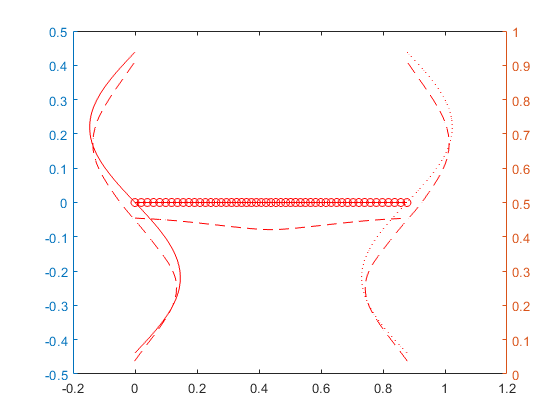

tarline = save_result.tardata;
resline = save_result.resdata;

L = tar.s(end);
for k = 1:3
    xt{k} = tarline{k,1} /L ;
    yt{k} = tarline{k,2} /L ;
    zt{k} = tarline{k,3} /L ;
    xr{k} = resline{k,1} /L ;
    yr{k} = resline{k,2} /L ;
    zr{k} = resline{k,3} /L ;
end
xr(end) = xt(end);
origin = [xt,yt,zt,xr,yr,zr];


figure
yyaxis left
for k = 1:3
    plot( xt{k}, yt{k},'r');
    hold on
    plot( xr{k}, yr{k},'--r');
end


yyaxis right
%plot( xt, zt,'b');
%plot( xr, zr,'--b');

%axis equal

hold off